clear; close; clc;

R_0 = 1;
x = [5;4];
gamma = .5;
mu = .5;

syms x1 x2
f = x1^2 + x2^2 - 2*x1 - 2*x2

$$f = {x_{1}}^{2}-2\,x_{1}+{x_{2}}^{2}-2\,x_{2}$$

diff(f,x1)

$$ans = 2\,x_{1}-2$$


A = [1, -10; 1, 0]; A'

ans =      1     1
   -10     0


b = [-5;-23]

b =     -5
   -23


c = [8;6]

c =      8
     6


H = eye(2)

H =      1     0
     0     1



options = optimoptions('quadprog', 'Display', 'iter'); % prepare options for quadprog
[d, ~, exitflag, ~, lambda] = quadprog(H, c, A', b, [], [], [], [], [2.3;-5], options);

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.
Solved 0 variables, 0 equality, and 1 inequality constraints during the presolve.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    5.527700e+01   8.360000e+00   8.360000e+00     4.180000e+00  
    1    3.229220e+00   9.466115e-01   9.466115e-01     1.927362e-01  
    2    3.908941e+00   4.733058e-04   4.733058e-04     1.486893e-02  
    3    3.890221e+00   2.366529e-07   2.366529e-07     1.697150e-04  
    4    3.890000e+00   1.183258e-10   1.183267e-10     1.069754e-07  
    5    3.890000e+00   5.950795e-14   5.684342e-14     5.349648e-11  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of

% step direction
d

d =     2.3000
   -7.3000


% lagrange multipiers of solution
v = lambda.eqlin % linear equality contraint lagrange multipliers -> rewrite to include if relevant


v =

  0×1 empty double column vector



u = lambda.ineqlin % linear inequality contraint lagrange multipliers

u =     1.3000
    1.1600


## plot the QP sub problem

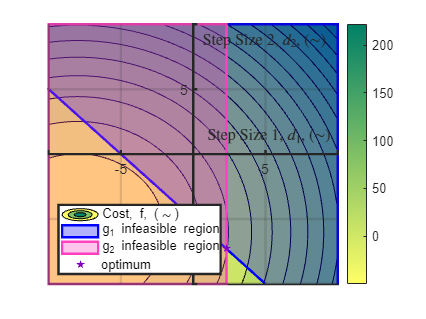

% declaration and initilaization
x_limits = [-10,10];
y_limits = [-10,10];

% set up plotting grid
x_1 = linspace(x_limits(1), x_limits(2));
x_2 = linspace(y_limits(1), y_limits(2));

[x_1_grid, x_2_grid] = meshgrid(x_1, x_2);

% evaluate cost function
f_tilde = c(1)*x_1_grid + c(2)*x_2_grid + 1/2*(x_1_grid.^2 + x_2_grid.^2);
f_tilde = 8*x_1_grid + 6*x_2_grid + 1/2*(x_1_grid.^2 + x_2_grid.^2);

% plot cost function
figure;
contourf(x_1_grid, x_2_grid, f_tilde, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap(flipud(summer)); colorbar;
hold on;

% evlauate constraint functions
g_1_tilde = A(1,1)*x_1_grid + A(1,1)*x_2_grid;
g_2_tilde = A(2,2)*x_1_grid + A(2,1)*x_2_grid;

% g1_tilde
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [-5 - x_1, y_limits(2) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,0,1], "FaceAlpha",.3, "EdgeColor",[0,0,1], "LineWidth",2, "DisplayName","g_1 infeasible region")

% g1_tilde
boundaryEdges_Xcoords = [23/10 * ones(size(x_1)), x_limits(1) * ones(size(x_1))];
boundaryEdges_Ycoords = [x_2, fliplr(x_2)];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [1,.25,.75], "FaceAlpha",.3, "EdgeColor",[1,.25,.75], "LineWidth",2, "DisplayName","g_2 infeasible region")

plot(d(1), d(2), "Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[.5,0,.75],"MarkerFaceColor",[.5,0,.75],"LineStyle","none", "DisplayName","optimum")

% make plot look good
xlim(x_limits); ylim(y_limits);
legend("Location","southwest")
set(gca,"FontSize",12)
set(gca,'BoxStyle','back','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)
xlabel("Step Size 1, $d_1$, $\left(\sim\right)$", "Interpreter","latex");
ylabel("Step Size 2, $d_2$, $\left(\sim\right)$", "Interpreter","latex");
grid on